# Particle Discovery Lab

### SETUP

Your first task is to load the CMS data file!

Download the MATLAB workspace for this exercise. Go to the Home menu, Environment section and select "Set Path" -- choose the location of your workspace file. Then run:

load('DoubleMuParked_100k.mat');

## PART 1 : RECONSTRUCTION

Use energy and momentum conservation to reconstruct a decay of particle X -> mu + mu.

Each element of the data contains 8 pieces of information in this order:

E1, E2, px1, px2, py1, py2, pz1, pz2

(where "1" refers to "muon 1" and "2" refers to "muon 2"). The default unit for these numerical values is the GeV.

First choose a number of events to process, and the boundaries of your analysis window:

% Choose how many events to process
Ntoprocess = input('How many events to process? ');

% Initialize a vector that will hold 1 invariant mass per event
Masses = [];
KineticEnergy = [];

% User-chosen min/max values and resolution
Min = input('Type in your min (in GeV): ');
Max = input('Type in your max (in GeV): ');
n = input('Type in the number of bins: ');
BinWidth = (Max - Min)/n;

% Loop over the number of events with at least 2 muons
disp(['Looping over ' num2str(Ntoprocess) ' events...']);

Looping over 100000 events...


Now we're ready to loop over the events in the data file and calculate the invariant mass of particle X. 

THINK: 

- How will you use the 8 pieces of information to calculate the mass of X?

- How can you save only the events with a mass value inside your window?

- How can you calculate the relativistic kinetic energy of particle X?

Write code to calculate the mass and KE of particle X. Store the results in Masses and KineticEnergy if the event has a mass inside your window.

for i = 1:Ntoprocess

    % COMPUTE the mass of particle X -> mu mu
    % Recall, the order of information stored in the list called data is given above.
    % The energy of muon number 1 can be accessed like data[i][1].

    Esum =
    Px =
    Py =
    Pz =
    M =

   if(M > Min && M < Max)
        
        % Calculate the Kinetic Energy of particle X. 
        % Store KE and mass values to plot later  
        % Tip: make sure your mass value is "real" by using real(massvalue)
        Masses = [Masses real(M)];  
        KineticEnergy = [KineticEnergy Esum - real(M)];
    end
end

## HISTOGRAMMING -- create mass and KE histograms

THINK: 

- What do you expect your kinetic energy histogram to look like? 

- What do you expect your mass histogram to look like? 

Make a quick sketch of what you expect for both plots

Vocab: imagine a plot with 3 bins on the x-axis: 0-10, 10-20, 20-30

- "Bin centers": 5, 15, 25 (want the dots on the plots to be here!)

- "Bin width": 10 (you already have this for mass)

- "Bin counts": the height of the histogram bar in each bin

**Draw a **`histogram` of counts versus mass. 

Tool:

- `histogram: `needs the Mass values list and a number of bins 

- Tip: store the histogram object itself! `h = histogram(...inputs...)`

Draw a `histogram` of counts versus mass. The `histogram` function needs: Mass values list, Mass "bin edges" list 

Create a MASS histogram by filling in the empty functions below when prompted to do so:

figure(1)
h = histogram(); %fill in histogram()
xlabel(); %fill in label()
ylabel(); %fill in label()
hold on; % this lets you draw on top of this plot later
axis manual; % this keeps the axes fixed to where they are now

h =   Histogram with properties:

             Data: [1×10666 double]
           Values: [111 109 126 143 130 99 127 105 109 93 112 118 138 152 174 281 430 791 1331 1790 1559 891 437 228 160 104 93 85 65 70 59 44 46 43 56 64 43 61 47 42]
          NumBins: 40
         BinEdges: [1×41 double]
         BinWidth: 0.0200
        BinLimits: [2.7000 3.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


THINK: 

- What should the error bars be for each bin? 

- What should you do if the bin has zero entries?

Tools: 

- `h`: this object has "properties" that include a list of all the bin edges and a list of all the y-axis values from your histogram

- `errorbar`: draws dots+bars, needs the bin centers list, y values list, down uncert list, up uncert list 

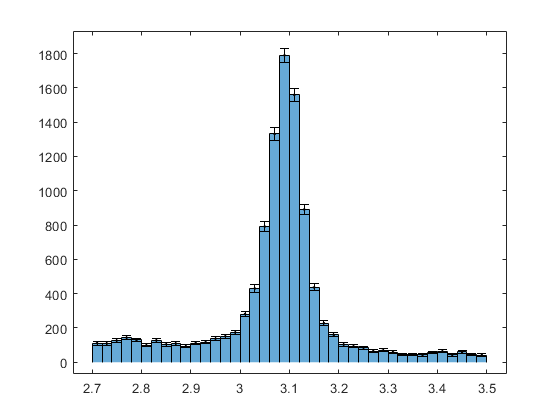

% Get lists of bin edges and y-axis values from the histogram
counts = ;
MassEdges = ;

% to check put variable for y-axis values into max()
disp(['Peak bin content: ' num2str(max())]);

% Define an array of bin centers
MassCenters = MassEdges(1:end-1) ; % finish the equation

% Make an errorbar plot for counts versus mass
error_up = ;        % avoid error of 0 going up

error_down = ;      % but error going down can be 0
errorbar();         % fill in errorbar()
hold off;

Draw another `histogram` of counts vs kinetic energy. Add error bars.

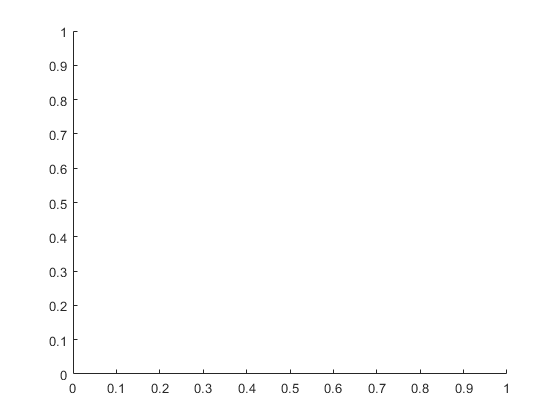

figure(2)
h2 = histogram(); %fill in histogram()
xlabel(''); %fill in label()
ylabel('');%fill in label()
hold on; % this lets you draw on top of this plot later
axis manual; % this keeps the axes fixed to where they are now



KEcounts = ;
KEedges = ;
KEwidth = ;

KEcenters = KEedges(1:end-1) ; % finish the equation
KEerror_up = ; % avoid error of 0 going up
KEerror_down = ; % but error going down can be 0
errorbar(); %fill in errorbar()
hold off;

## Great work! 

- **SAVE** these plots to represent your raw data in your report.

## PART 2 : BACKGROUND ESTIMATION 

Fit background on either side of the peak

Vocab: imagine a mass plot with a bump in the middle

- "Peak window": region along x-axis under the peak

- "background": smoothly falling slope of random events, including some of the events in the peak window

- "signal": events in the peak window minus the background

CHOOSE mass values or bin numbers for where the peak lies. 

peakmin = input('Type in your peak min boundary (in GeV): ');
peakmax = input('Type in your peak max boundary (in GeV): ');

% Convert these mass values into bin numbers:
iMin = 
iMax = 

**PERFORM a line fit to the background**

    THINK: Imagine a line connecting the data on either side of your peak.  How could you estimate the function of that line?

% Using data points from the left and right sides of your mass histograms, evaluate a linear function to represent the background events underneath the peak. 
% Recall, the function of a line is y = mx + b


m = ;
b = ;

fittedCounts = MassCenters;
for n = 1 : length(fittedCounts)
    fittedCounts(n) = (m * fittedCounts(n)) + b
end

figure(3)
errorbar(); %fill in errorbar()
xlabel(''); %fill in label()
ylabel(''); %fill in label()
hold on;
plot() %fill in plot()
hold off;

## SUBTRACTION -- now you will subtract that background from data

THINK: 

- Are your estimated background values at all uncertain?

- How could you evaluate an uncertainty on the number of background event in each bin?

- What do you expect the curve to look like after background subtraction?

EVALUATE signal = data - background

THINK: 

- Do you have any bins where the background estimate is larger than the data? What do you think about this situation? 

- How could you find the uncertainty in data - background?

% Subtract background and plot the resulting signal-only peak with error bars
sigcount = ;
sigerror_up = ; % again, up error not 0
sigerror_down = ;

PLOT the signal-only peak with ERROR BARS

figure(5)
errorbar(); %fill in errorbar()
xlabel(''); %fill in label()
ylabel(''); %fill in label()

## Great work! 

- **SAVE** the data+background and signal-only plots as analysis in your report.

## PART 3 : CHARACTERIZATION of your signal

Determine which particle you've discovered and use a fit to find its properties

EXTRACT the characteristics of your signal peak

THINK: Which statistical distribution describes your signal peak?

**TOOL nlinfit: fits a given nonlinear function to data **

- outputs: [paramsGaus, R, J, covariance]. We don't care about R or J, but want "params" (the fitted function parameters) and "covariance" (uncertainty squared for each parameter runs down the diagonal).

- inputs: nlinfit(x-axis data, y-axis data, function handle, initial parameter guess)

- usage example: [paramsGaus, R, J, covariance] = nlinfit(X, Y, @functionName, guess)

Looking at your mass histogram, guess the inital conditions of the Gaussian distribution that would destribe your signal peak.  

You will need to guess the amplipitude, the mean, and the standard deviation.

THINK: what do the parameters represent?

% Create an initial guess vector
% Fill in the guesses with three number each seperated by commas
if Min < 4
    guess = [ , , ];
elseif Min < 20
    guess = [ , , ]; % first/tallest peak
else
    guess = [ , , ];
end

Call **nlinfit** on your signal peak using the function **gausfit.**  

[paramsGaus,R,J,covariance] = nlinfit(MassCenters,sigcount,@gausfit,guess); 


EXTRACT the **mean** and **width** of your fitted curve. 

Print these values with their uncertainties.

mu = paramsGaus(2);                     % order is N, mu, sigma
mu_uncert = sqrt(covariance(2,2));      % picking the diagonal element gives uncert^2          
sigma = paramsGaus(3);                      
sigma_uncert = sqrt(covariance(3,3)); 

disp(['Gaussian mean = ' num2str(mu) ' +/- ' num2str(mu_uncert)]);
disp(['Gaussian width = ' num2str(sigma) ' +/- ' num2str(sigma_uncert)]);


PLOT the Gaussian fit on top of your signal peak as a final figure. Include a LEGEND. 

gaus_x = Min:(Max-Min)/100:Max;
gaus_y = gausfit(paramsGaus,gaus_x);

figure(6)
errorbar(MassCenters,sigcount,sigerror_up,sigerror_down,'b.'); 
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on
plot(gaus_x,gaus_y,'k')
legend('data','Gaussian fit','Location','best')

COMPARE the number of signal events in signal peak window to the number of background events under the peak window.

THINK: 

- How can you find the number of events in the signal peak? 

- How can you find the number of bkg events under the peak?

PRINT these values along with their uncertainties

bkginpeak = fittedcounts(iMin:iMax-1);
peakcounts = counts(iMin:iMax-1);
siginpeak = sigcount(iMin:iMax-1);

disp(['Number of background events in peak = ' num2str(sum(bkginpeak))...
     ' +/- ' num2str(sqrt(sum(bkginpeak)))]);
disp(['Number of signal events in peak = ' num2str(sum(siginpeak))...
     ' +/- ' num2str(sqrt(sum(peakcounts+bkginpeak)))]);


## Almost done!

THINK: 

- Can you statistically distinguish signal from background?

- Can you find this particle with a web search for you mass?

Research this particle (https://pdg.lbl.gov), find its width (capital Gamma)

- Do your mass & width agree with the known values within their uncertainties? 

- Find percent differences and also discrepancy/significance.

- If your width is *much* larger than accepted, why might this be?

## Great work! 

Save plots and all the numerical values (mean, width, Nsignal, Nbackground, all with uncertainties, percent differences, discrepancy significances) for the Results section of your report.